# **基于机器学习的ECG分类模型**

### 研究背景与意义

心血管疾病已成为目前全球非传染性疾病的主要死因，每年死于心血管疾病的人数高于任何其他死因。由于高患病率与高死亡率，心血管疾病给人们不断的带来越来越重的负担，其逐渐成为研究的热点课题。心律失常是一种常见的心血管综合征，心脏电刺激的起源位置异常、传导顺序异常和频率改变均会造成心律失常，是目前临床心血管疾病治疗所面临的重大难题。

目前广泛应用于心律失常检测的方法是心电图（Electrocardiogram，ECG）诊断。心律失常是一种极其常见而又非常重要的心电活动异常状态，不同的心律异常类型，在心电图波形以及心电图频率上会呈现出不同的状态，研究心电信号可以对多种心律失常症状进行诊断。采取有效措施检测心律失常的发生对心血管疾病的预防和诊断具有很大积极作用，具有十分重要的临床意义。

本程序主要分析处理正常心电及三种常见心律失常类型:

（1）正常搏动（Normal beat，**N**）

（2）左束支阻滞（Left bundle branch block beat，**L**）：左束支在心脏电激动传导过程中可能出现的传导异常中断。在心电图中主要特点是R波的宽峰出现顿挫，时限一般不小于0.11s。

（3）右束支阻滞（Left bundle branch block beat，**R**）：右心室壁在心脏电激动传导过程可能发生的阻滞异常。在心电图中的主要特点是QRS波形可能发生改变，如增宽、时限延长、粗顿等。

（4）室性早搏（Premature ventricular contraction，**V**）：心室在心脏电激动传导到心室之前可能提前发生激动异常。在心电图中的主要特点是提早出现QRS波群，且一般认为QRS波群范围变宽大。

数据来源于MIT-BIH Arrhythmia Database（[MIT-BIH Arrhythmia Database v1.0.0 (physionet.org)](https://physionet.org/content/mitdb/1.0.0/)，本程序都取MLII导联方式测得的数据（通过将电极置于胸部而获得），即37条心电数据。

## 一、用wfdb库导入所需数据

clear,clc,close all;

fileID = fopen('database\mitdb\RECORDS.txt','r');% 打开文件
data = textscan(fileID, '%s');% 读取数据
fclose(fileID);% 关闭文件
file_names = data{1};% 将数据存储到数组中
data_original = cell(length(file_names), 1);% 创建一个37x1的空元胞数组

% 读取数据
for i = 1:length(file_names)
    [signal, Fs, tm] = rdsamp(['database\mitdb\', file_names{i}], 1);
    data_original{i} = signal;
end
save('data_original.mat', 'data_original');

## 二、将提取到的心电数据进行小波阈值去噪

在对心电信号进行分析前，需要对其进行去噪预处理。因为在心电信号采集或者数模转换的过程中，会产生噪声，包括工频干扰、肌电干扰、基线漂移这三种。本程序将介绍目前十分常用且有效的一种去噪方法——小波阈值去噪。

**信噪比SNR越大，均方差值MSE越小，说明去噪效果越好。**

wave_thresh;%可尝试第一种去噪方法wave_thresh_v1进行对比

## 三、提取人工注释信息划分心拍

**ANNOT：存储了该记录中各心拍的人工标注类型。**ANNOT文件中的数字，分别代表了当时人工标注的心脏的情况它提供给了我们各心拍专家诊断的结果，用于后续深度学习算法的标签。

**ATRTIME：存储了各心拍的人工标注位置。**即它记录了数据中几分几秒出现了一个心拍。而这个矩阵的意义在于后续帮助我们评估心拍定位算法的准确性，或是直接根据它提供的人工标注位置截取心拍。

beat_division;

## 四、提取心电信号特征

根据葛丁飞等人的利用MDL和 MDL敏感性函数作为准则进行模型定阶[[1]](https://www.cnki.com.cn/Article/CJFDTOTAL-YYGC200401003.htm)，或者根据毛雪岷等人所提出的按照信噪比和赤池信息量准则进行定阶[[2]](http://cjbme.csbme.org/CN/abstract/abstract532.shtml)，结果都可以表明**当 n = 4，m = 2 时，模型拟合得到的信号与原始心电信号最为相似。**因此本程序选用ARMA(4,2)模型，通过ARMA_coeffs脚本来建立模型，输出拟合的模型系数。

由于约 N样本信号的比例过大，因此分类器会发现通过简单地将所有信号分类为正常信号就可达到高准确度。为了避免这种偏置，可以通过复制数据集中的 L,R,V 信号来增加数据，以便N信号和 L,R,V 信号的数量相同。这种复制通常称为上采样（也叫过采样），是深度学习中使用的一种数据增强形式。

此外还可以通过减少N样本的数量，同样达到N信号和 L,R,V 信号的数量相同的效果。这种减少多数样本数量通常称为下采样。

因考虑到运行时间和电脑内存限制，**本程序采用下采样的方式，将L,N,R,V样本数量都控制在5000**。

ARMA_coeffs;

在ARMA模型中，系数（coefficients）指的是ARMA模型中的参数，包括常数项（constant）和AR、MA阶数对应的参数。

在MATLAB中，estimate函数返回的est_mdl结构体包含了ARMA模型的系数（coefficients），以及系数的估计标准误（standard error）、t统计量（t statistic）和p值（p-value）等信息。具体来说：

- 系数（coefficients）指的是ARMA模型的各个参数的值，包括常数项（constant）和AR、MA阶数对应的参数。

- 估计标准误（standard error）是指对系数的估计标准误差，用于度量估计系数的精度和可靠性。

- t统计量（t statistic）是指系数估计值除以其标准误后得到的值，用于检验系数是否显著不为零。

- p值（p-value）是指对于给定的显著性水平，拒绝原假设的最小显著性水平，用于判断系数是否显著不为零。

例如，对于一个ARMA(2,2)模型，ARMA模型系数中value、standarderror、tstatistic、pvalue分别表示模型中的常数项（constant）、AR(1)、AR(2)、MA(1)、MA(2)的系数、标准误差、t统计量和p值。其中，value(1)表示常数项的系数，value(2)和value(3)分别表示AR(1)和AR(2)的系数，value(4)和value(5)表示MA(1)和MA(2)的系数。

需要注意的是，在使用ARMA模型进行分析时，需要对模型参数和估计结果进行全面的评估和分析，不能仅仅依赖于单个系数或指标来做出结论。

## 五、进行支持向量机SVM分类

支持向量机是一种监督学习的二分类模型，其主要目的是找到一种超平面对样本数据进行分割，从而转化为求解凸二次规划的问题。然而在大部分的分类任务中，一般无法使用一种线性关系将两种分类实例分割，支持向量机模型通过非线性核函数将分类任务从线性不可分的低维空间转换到线性可分的高维空间，然后通过算法分析找出最佳超平面，最后返回到原始空间以获得初始空间的解。

要将上述四类心搏样本数据的ARMA模型系数进行支持向量机分类，可以采取以下步骤：

1.将四类心搏样本数据的ARMA模型系数合并成一个矩阵`ARMA_coeffs`，将四类心搏样本的标签分别用1、2、3、4表示，并将标签数据合并成一个向量。

% 合并数据
ARMA_coeffs = [ARMA_coeffs_L; ARMA_coeffs_N; ARMA_coeffs_R; ARMA_coeffs_V];
labels = [ones(size(ARMA_coeffs_L,1),1); 2*ones(size(ARMA_coeffs_N,1),1); 3*ones(size(ARMA_coeffs_R,1),1); 4*ones(size(ARMA_coeffs_V,1),1)];

2.将合并后的矩阵随机划分为训练集、验证集和测试集，并且比例为0.7：0.2：0.1。

%数据集按比例划分
train_ratio = 0.7;
val_ratio = 0.2;
test_ratio = 0.1;
data_split;

3.使用MATLAB内置的fitcsvm函数对训练集进行支持向量机模型训练。训练时需要输入训练集数据和训练集标签。训练完成后，返回一个SVMModel对象，即训练好的支持向量机模型。

% 训练SVM模型
SVMModel = fitcecoc(train_set, train_labels);%fitcsvm函数只分类两类

## 六、性能评估

在机器学习领域，混淆矩阵（Confusion Matrix）是一种常见的评估模型性能的方式，通常用于评估分类问题中的模型性能。混淆矩阵是一个二维矩阵，其中每行表示真实类别，每列表示预测类别。对于二分类问题，混淆矩阵如下：

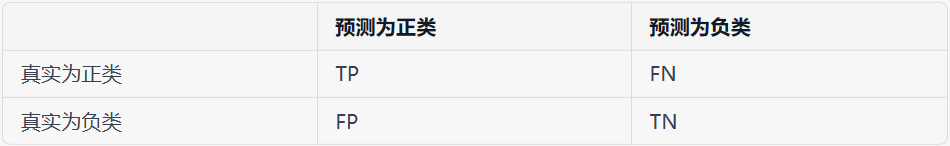

其中，TP表示真正例数（True Positive），即将正例预测为正例的数量；FN表示假反例数（False Negative），即将正例预测为负例的数量；FP表示假正例数（False Positive），即将负例预测为正例的数量；TN表示真反例数（True Negative），即将负例预测为负例的数量。

混淆矩阵能够直观地反映出分类模型的性能。通过混淆矩阵，可以计算出各种评估指标，例如精确度（Precision）、召回率（Recall）、F1值等。例如，对于二分类问题，精确度、召回率、F1值的计算公式如下：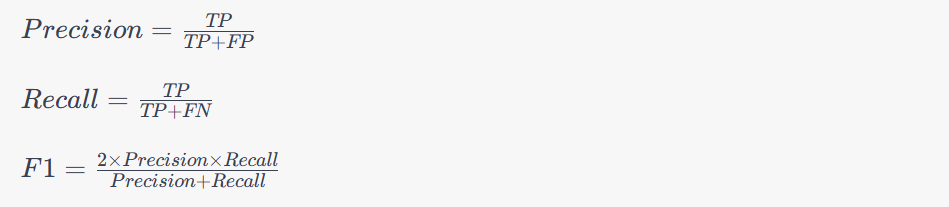

使用predict函数对验证集和测试集进行预测。predict函数需要输入训练好的支持向量机模型和待预测的数据。预测结果返回一个预测标签向量。

% 预测验证集和测试集
val_pred = predict(SVMModel, val_set);
test_pred = predict(SVMModel, test_set);

使用MATLAB内置的confusionmat函数计算出验证集和测试集的混淆矩阵。该函数需要输入真实标签向量和预测标签向量，返回混淆矩阵。

% 绘制混淆矩阵
heatmap_plot;

6.保存训练好的支持向量机模型，可以使用MATLAB内置的save函数将模型保存在本地磁盘上。

% 保存学习后的模型
save('SVMModel.mat', 'SVMModel');

# **Pan-Tompkins法**

Pan-Tompkins法是一种用于心电图（ECG）信号处理中的心率检测算法，它可以检测出心电图中的QRS波群，即心脏电激动的主要特征之一。Pan-Tompkins法是一种基于波形形态的方法，通过分析QRS波群在ECG信号中的形态特征，来确定心率。

Pan-Tompkins法的主要思想是通过分析ECG信号的斜率、幅度和宽度等特征，来检测QRS波群的起始点和终止点。该算法包括以下主要步骤：

- 滤波：首先对原始ECG信号进行滤波，通常使用带通滤波器，以去除噪声和突发干扰。

- 导联选择：选择一个合适的导联，通常选择I导联，因为它在QRS波群的形态上最为明显。

- 特征提取：计算QRS波群在ECG信号中的斜率、幅度和宽度等特征。一般来说，QRS波群在ECG信号中的斜率较大、幅度较大且宽度较窄，这些特征可以用来检测QRS波群的起始点和终止点。

- 基线漂移校正：对QRS波群的斜率特征进行基线漂移校正，以消除ECG信号的基线漂移对QRS波群检测的影响。

- 积分：对校正后的QRS波群斜率特征进行积分，得到QRS波群的幅度特征。

- 移动平均：对QRS波群的幅度特征进行移动平均，以平滑幅度特征并降低噪声的影响。

- 判定阈值：根据移动平均后的幅度特征，确定QRS波群的判定阈值，用来检测QRS波群的起始点和终止点。

- 检测：根据判定阈值，检测QRS波群的起始点和终止点，从而得到心率信息。

Pan-Tompkins法在心电图信号处理中应用广泛，其优点是能够实时、准确地检测QRS波群，对噪声和基线漂移具有较强的抗干扰能力。但同时也存在一些局限性，例如对QRS波群形态的要求较高，对心律不齐和心率较快的情况可能不太适用。因此，虽然Pan-Tompkins法在许多情况下是一种有效的QRS波群检测算法，但在实际应用中，需要根据具体的临床场景和ECG信号特点来选择合适的算法和参数。同时，Pan-Tompkins法通常用于单导联的QRS波群检测，对于多导联的QRS波群检测，可能需要结合其他方法或者进行导联融合。

需要注意的是，作为一种心率检测算法，Pan-Tompkins法主要用于初步的QRS波群检测，可以用于计算心率和测量心律的基本参数。在实际临床应用中，还需要结合医生的临床判断和其他检查结果，以作出准确的诊断和治疗决策。

# **结论**

待完善。。。

# **后期设想**

**将支持向量机模型保存到STM32微控制器上，以便用该模型分类stm32采集到的心电数据，并通过上位机呈现采集到的心电波形以及分类结果。**

需要进行以下步骤：

- 将模型参数转换为可供STM32使用的格式：通常情况下，SVM模型是用MATLAB等高级编程语言训练的，并以某种形式保存。将模型参数转换为C语言格式是将模型移植到STM32所必需的。可以使用MATLAB的codegen功能将模型编译成可嵌入式平台使用的C代码，或者手动将模型参数导出为C语言头文件。

- 在STM32项目中添加模型代码：将模型代码添加到STM32项目中，通常是作为一个单独的源文件或库。

- 调用模型函数进行预测：在STM32代码中调用模型函数进行预测。通常，这涉及将输入数据作为函数参数传递给模型，然后读取模型的输出。

需要注意的是，将SVM模型移植到STM32上需要考虑到微控制器的内存、处理能力等限制。可能需要对模型进行优化或削减，以确保在STM32上能够快速、有效地执行。

# **参考资料**

[1] 葛丁飞，李时辉.基于ARMA模型的ECG分类和压缩[J].浙江科技学院学报，2004（01）：7-13.

[2] 毛雪岷，张婷婷，蔡传晰，李琼.基于ARMA模型的心电聚类算法[J].中国生物医学工程学报，2012，31（06）：816-821.

[3] 基于机器学习的心律失常分类(一)——基本理论介绍 - 知乎([https://zhuanlan.zhihu.com/p/144855071](https://zhuanlan.zhihu.com/p/144855071))

[4] MIT-BIH心律失常数据库详解_心跳脉搏数据库_海狸小生的博客-CSDN博客([https://blog.csdn.net/Mrm_cong/article/details/104668271](https://blog.csdn.net/Mrm_cong/article/details/104668271))